# **Load Data**

Data = readtable("Preprocess data\Final Measure Unique.xlsx","TextType","string")

Data = 78723×6 table
         Measure_Name                                                               Description                                                                                                             Whole_Data_unique                                                                                                         Whole_Data_unique_1                                                                                                        Whole_Data_unique_2                                                                                                        Whole_Data_unique_3                                                  
    ______________________    _______________________________________________________________________________________________________________________    ________________________________________

# **Preprocessing **

Data_pre=preprocessText(Data.Description)

Data_pre =   78723×1 tokenizedDocument:

     3 tokens: air sealing gas
    12 tokens: boiler reset control retrofit boiler reset control retrofit add boiler reset control
    10 tokens: boiler reset control retrofit boiler reset control boiler reset control
     9 tokens: boilers90 boiler forced hot water 90 afue boiler 90
     8 tokens: boilers90 hot water boiler 90949 afue boiler 90
     9 tokens: boilers95 boiler forced hot water 95 afue boiler 95
     8 tokens: boilers95 hot water boiler 95 afue boiler 95
     0 tokens:
     2 tokens: cfl bulb
    11 tokens: combo water heater 90 cd combo condensing boiler water heater 90
    11 tokens: combo water heater boiler 90 combo condensing boiler water heater 90
    15 tokens: combo water heater boiler 90 condensing boiler 90949 afue combo condensing boiler water heater 90
    14 tokens: condens gas water heater 95 condensing wh 95 thermal efficiency condensing wate

# **Bag Of Ngrams Model**

N_bag = bagOfNgrams(Data_pre)

N_bag =   bagOfNgrams with properties:

          Counts: [78723×127756 double]
      Vocabulary: [1×52382 string]
          Ngrams: [127756×2 string]
    NgramLengths: 2
       NumNgrams: 127756
    NumDocuments: 78723


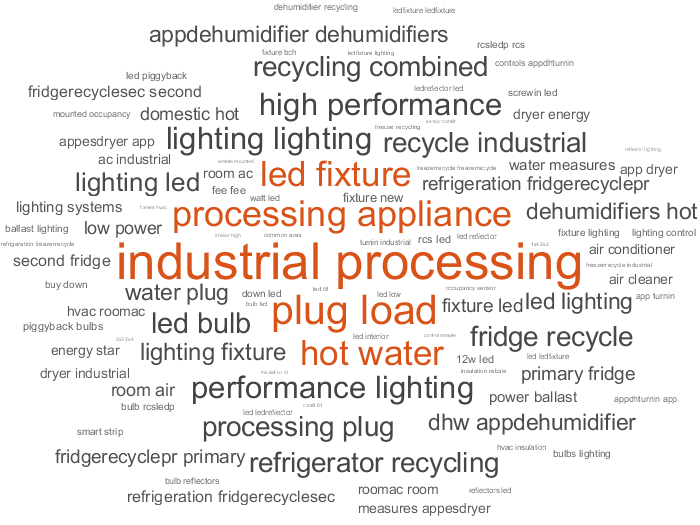

NGram_CLoud =   WordCloudChart with properties:

           WordData: [1×127756 string]
           SizeData: [1×127756 double]
    MaxDisplayWords: 100

  Show all properties



figure
NGram_CLoud = wordcloud(N_bag)


NGram_table = topkngrams(N_bag,20)

NGram_table = 20×3 table
                 Ngram                 Count    NgramLength
    _______________________________    _____    ___________

    "industrial"      "processing"     16271         2     
    "plug"            "load"           11014         2     
    "processing"      "appliance"       9286         2     
    "hot"             "water"           8772         2     
    "led"             "fixture"         8727         2     
    "performance"     "lighting"        7396         2     
    "lighting"        "lighting"        7075         2     
    "high"            "performance"     7068         2     
    "led"             "bulb"            6260         2     
    "processing"      "plug"            6050         2     
    "refrigerator"    "recycling"       6044         2     
    "recycling"       "combined"        6043         2     
    "fridge"          "recycle" 

# **LDA model **

numTopics = 14; % number of unique "End_Use" in "Final Measure Group"

mdl = fitlda(N_bag,numTopics);

Initial topic assignments sampled in 1.71421 seconds.
| Iteration  |  Time per  |  Relative  |  Training  |     Topic     |     Topic     |
|            | iteration  | change in  | perplexity | concentration | concentration |
|            | (seconds)  |   log(L)   |            |               |   iterations  |
|          0 |     115.39 |            |  3.799e+03 |         3.500 |             0 |
|          1 |     120.07 | 2.0619e-01 |  9.285e+02 |         3.500 |             0 |
|          2 |     117.44 | 8.3870e-04 |  9.232e+02 |         3.500 |             0 |
|          3 |     117.38 | 3.3515e-04 |  9.210e+02 |         3.500 |             0 |
|          4 |     122.26 | 3.2916e-04 |  9.190e+02 |         3.500 |             0 |
|          5 |     119.77 | 1.0477e-04 |  9.183e+02 |         3.500 |             0 |


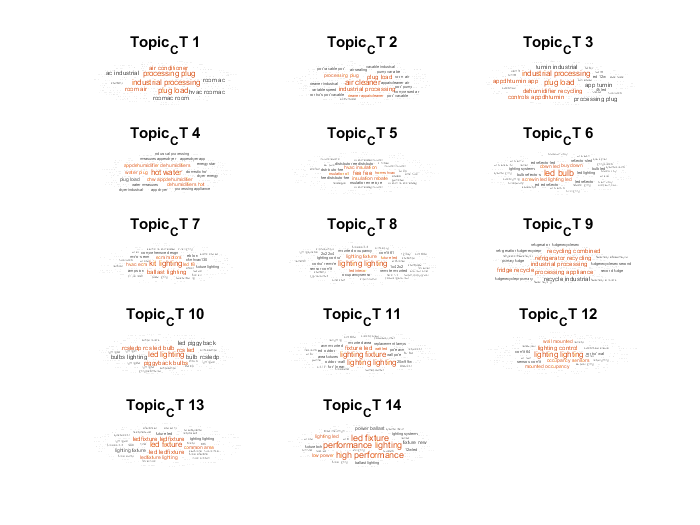


figure
for topicIdx_CT = 1:14
     subplot(5,3,topicIdx_CT)
    wordcloud(mdl,topicIdx_CT);
    title("Topic_CT " + topicIdx_CT)
end

# **Set aside 10% of the documents at random for validation**

numDocuments = numel(Data_pre)

numDocuments = 78723

cvp = cvpartition(numDocuments,'HoldOut',0.1)

cvp = Hold-out cross validation partition
   NumObservations: 78723
       NumTestSets: 1
         TrainSize: 70851
          TestSize: 7872

documentsTrain = Data_pre(cvp.training)

documentsTrain =   70851×1 tokenizedDocument:

     3 tokens: air sealing gas
    10 tokens: boiler reset control retrofit boiler reset control boiler reset control
     9 tokens: boilers90 boiler forced hot water 90 afue boiler 90
     9 tokens: boilers95 boiler forced hot water 95 afue boiler 95
     8 tokens: boilers95 hot water boiler 95 afue boiler 95
     0 tokens:
     2 tokens: cfl bulb
    11 tokens: combo water heater 90 cd combo condensing boiler water heater 90
    11 tokens: combo water heater boiler 90 combo condensing boiler water heater 90
    15 tokens: combo water heater boiler 90 condensing boiler 90949 afue combo condensing boiler water heater 90
    14 tokens: condens gas water heater 95 condensing wh 95 thermal efficiency condensing water heater 095
    11 tokens: condenboilerdhwafue95 condensing boiler 95 afue combo condensing boiler water heater 95
    13 tokens: condenboilerdhwafue95 cond

documentsValidation = Data_pre(cvp.test)

documentsValidation =   7872×1 tokenizedDocument:

    12 tokens: boiler reset control retrofit boiler reset control retrofit add boiler reset control
     8 tokens: boilers90 hot water boiler 90949 afue boiler 90
    11 tokens: ecmfurnace95 furnace forced hot air 95 afue ecm furnace ecm 95
     8 tokens: ecmfurnace97 furnace ecm 97 afue furnace ecm 97
    16 tokens: alone water heater67 high efficiency stand alone water heater 067 ef stand alone water heater 067
     9 tokens: heat recovery ventilator heat recovery ventilator heat recovery ventilator
    12 tokens: indirect water heater attached indirect wh ngas hw boiler indirect water heater
     9 tokens: water heaters gas storage stand alone water heater 067
     5 tokens: 125w led t8 lpb lighting
     6 tokens: 15hp vfd way valve control motor
     5 tokens: 19 scissor lift week lighting
     5 tokens: ton bvrmc3948s4n3 york ycjd48s43s3 cooling
     4 token

numTopicsRange = [5 10 15 20 40]

numTopicsRange =      5    10    15    20    40


for i = 1:numel(numTopicsRange)
    numTopics_Un = numTopicsRange(i)
    
    mdl = fitlda(N_bag,numTopics_Un,'Solver','savb','Verbose',0);
    
    [~,validationPerplexity(i)] = logp(mdl,documentsValidation);
    timeElapsed(i) = mdl.FitInfo.History.TimeSinceStart(end);
end

numTopics_Un = 5

numTopics_Un = 10

numTopics_Un = 15

numTopics_Un = 20

numTopics_Un = 40

# ** The perplexity and elapsed time for each number of topics in a plot**

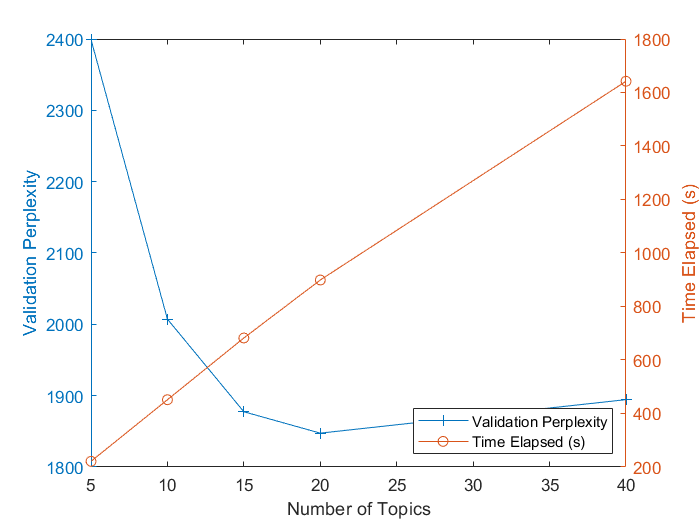

figure
yyaxis left
plot(numTopicsRange,validationPerplexity,'+-')
ylabel("Validation Perplexity")

yyaxis right
plot(numTopicsRange,timeElapsed,'o-')
ylabel("Time Elapsed (s)")

legend(["Validation Perplexity" "Time Elapsed (s)"],'Location','southeast')
xlabel("Number of Topics")

# **LDA model **

numTopics_NEW = 20

numTopics_NEW = 20


mdl = fitlda(N_bag,numTopics_NEW);

Initial topic assignments sampled in 1.66384 seconds.
| Iteration  |  Time per  |  Relative  |  Training  |     Topic     |     Topic     |
|            | iteration  | change in  | perplexity | concentration | concentration |
|            | (seconds)  |   log(L)   |            |               |   iterations  |
|          0 |     156.65 |            |  3.688e+03 |         5.000 |             0 |
|          1 |     154.56 | 2.2296e-01 |  8.251e+02 |         5.000 |             0 |
|          2 |     154.59 | 1.0922e-03 |  8.190e+02 |         5.000 |             0 |
|          3 |     153.98 | 2.1700e-04 |  8.179e+02 |         5.000 |             0 |
|          4 |     153.30 | 3.4618e-04 |  8.160e+02 |         5.000 |             0 |
|          5 |     153.62 | 1.5430e-04 |  8.151e+02 |         5.000 |             0 |


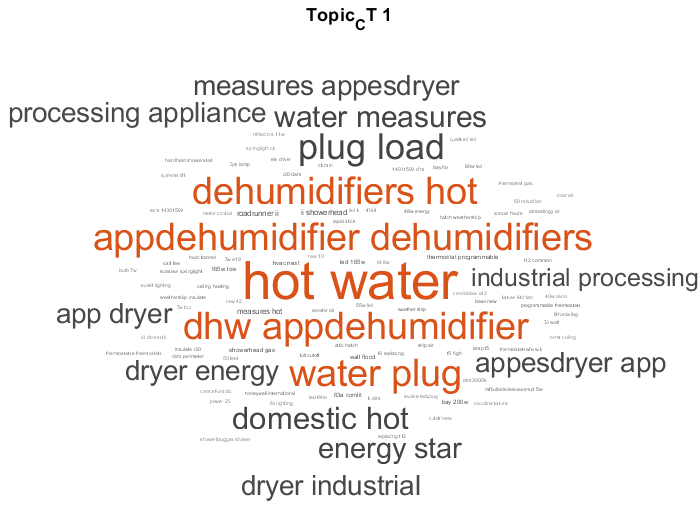

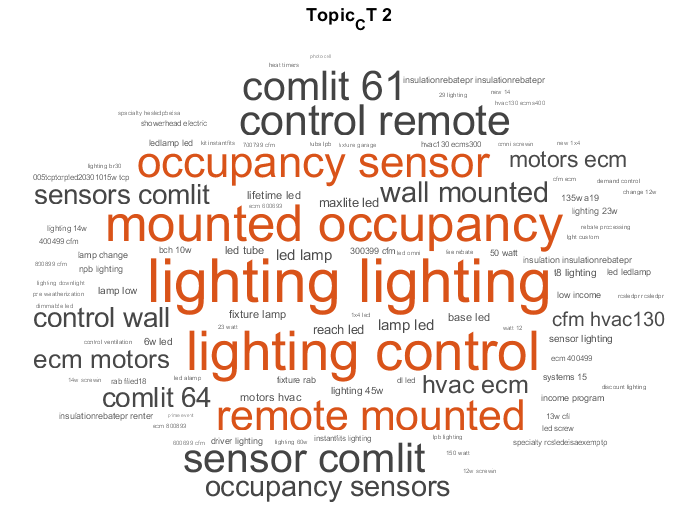

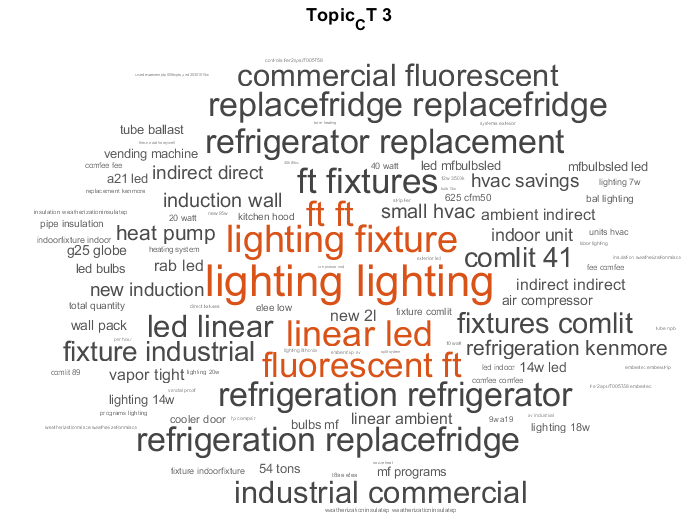

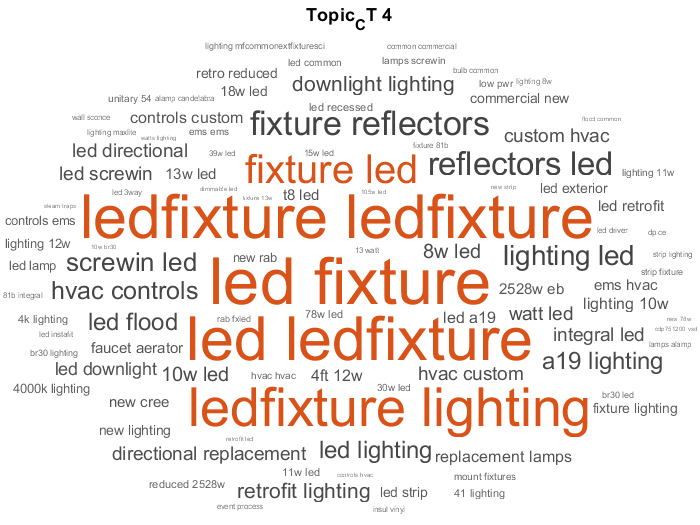

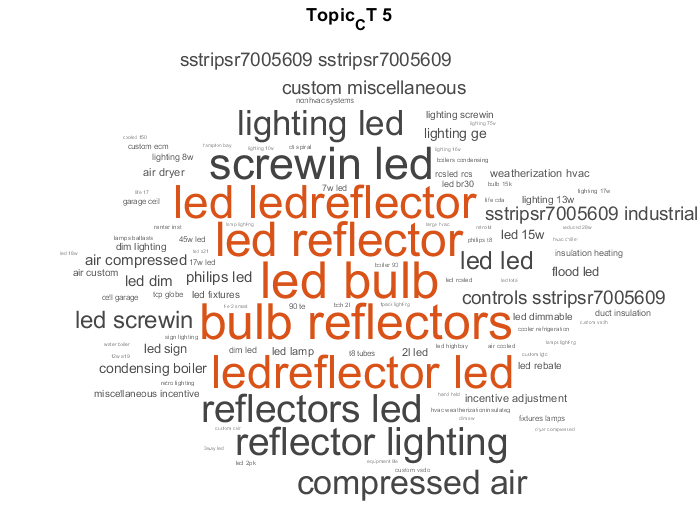

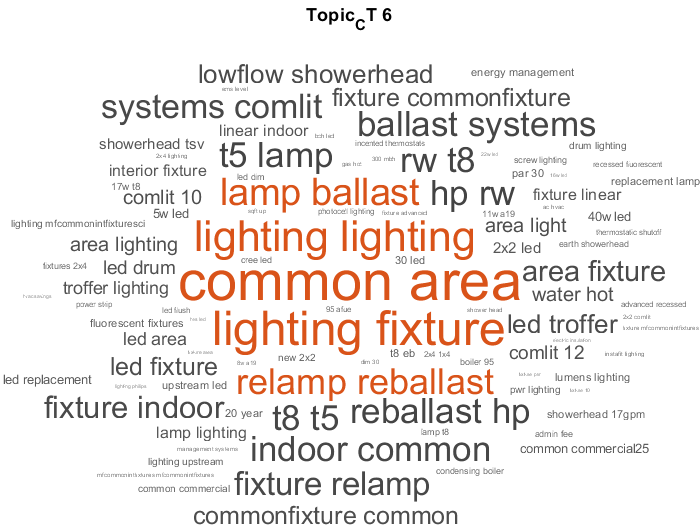

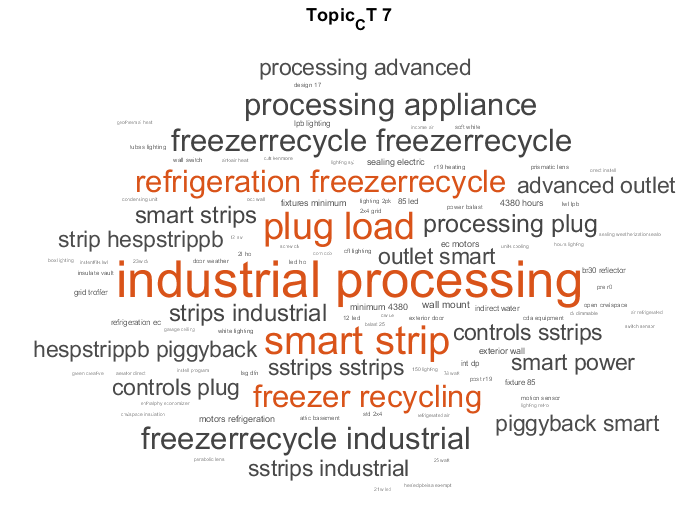

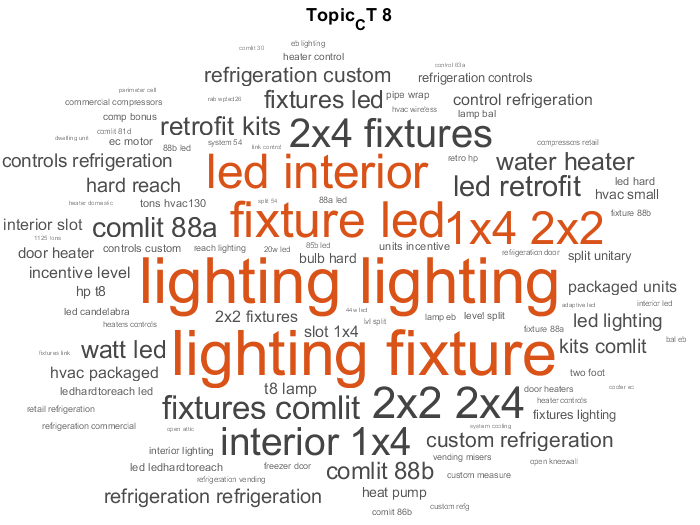

figure
for topicIdx_NEW = 1:20
     figure
    wordcloud(mdl,topicIdx_NEW);
    title("Topic_CT " + topicIdx_NEW)
end

function Note = replaceDocument(origndata)

Note=replace(origndata,'br20 ','screw-in led ');
Note=replace(Note,'par20 ','screw-in led ');
Note=replace(Note,'par30 ','screw-in led ');
Note=replace(Note,'br40 ','screw-in led ');
Note=replace(Note,'par38 ','screw-in led ');
Note=replace(Note,'mr16 ','screw-in led ');
Note=replace(Note,'a-line, 75/100w ','screw-in led ');
Note=replace(Note,'a-line, 40/60w ','screw-in led ');
Note=replace(Note,'a-line ','screw-in led ');
Note=replace(Note,'decoratives ','screw-in led ');
Note=replace(Note,'retrofit kit ','screw-in ');
Note=replace(Note,'stairwell kit ','linear led ');
Note=replace(Note,'g24 led ','screw-in led ');
Note=replace(Note,'g23 led ','screw-in led ');
Note=replace(Note,'2x4 led fixture standard w controls ','linear led ' );
Note=replace(Note,'2x4 led fixture premium w controls ','linear led ' );
Note=replace(Note,'2x2 led fixture standard w controls ','linear led ' );
Note=replace(Note,'2x2 led fixture premium w controls ','linear led ');
Note=replace(Note,'1x4 led fixture standard w controls ','linear led ');
Note=replace(Note,'1x4 led fixture premium w controls ','linear led ');
Note=replace(Note,'2x4 led fixture standard ','linear led ');
Note=replace(Note,'2x4 led fixture premium ','linear led ');
Note=replace(Note,'2x2 led fixture standard ','linear led ');
Note=replace(Note,'2x2 led fixture premium ','linear led ');
Note=replace(Note,'1x4 led fixture standard ','linear led ');
Note=replace(Note,'1x4 led fixture premium ','linear led ');
Note=replace(Note,'t8 tled ','linear led ');
Note=replace(Note,'t5 led ','linear led ');
Note=replace(Note,'u-bend led ','linear led ');
Note=replace(Note,'led troffer retrofit kit ','linear led ');
Note=replace(Note,'led ambient/strip/wrap ','linear led ');
Note=replace(Note,'mogul ext ','exterior led ');
Note=replace(Note,'led tubes ','linear led ');
Note=replace(Note,'parking garage ','exterior led ');

end

function predata = preprocessText(textData)

predata=lower(textData);
predata=replaceDocument(predata);
predata=strtrim(predata);
predata=tokenizedDocument(predata);
predata=erasePunctuation(predata);
predata=removeWords(predata,"unknown");
predata=removeStopWords(predata);
predata=removeShortWords(predata,1);

end